clear; clc; close all;

% system('run_win.bat');

% filename = 'data_wo_ctrl.csv';
% filename = 'data_p500.csv';
filename = 'data_squat.csv';

T = readtable(filename); %check T.Properties

Arr = table2array(T);
t = Arr(:, 1);

% Trunk
pos_trunk_des_x = Arr(:, 2);
pos_trunk_des_y = Arr(:, 3);
pos_trunk_des_z = Arr(:, 4);

pos_trunk_act_x = Arr(:, 5);
pos_trunk_act_y = Arr(:, 6);
pos_trunk_act_z = Arr(:, 7);

rot_trunk_des_x = Arr(:, 8);
rot_trunk_des_y = Arr(:, 9);
rot_trunk_des_z = Arr(:, 10);

rot_trunk_act_x = Arr(:, 11);
rot_trunk_act_y = Arr(:, 12);
rot_trunk_act_z = Arr(:, 13);

vel_trunk_des_x = Arr(:, 14);
vel_trunk_des_y = Arr(:, 15);
vel_trunk_des_z = Arr(:, 16);

vel_trunk_act_x = Arr(:, 17);
vel_trunk_act_y = Arr(:, 18);
vel_trunk_act_z = Arr(:, 19);

omega_trunk_des_x = Arr(:, 20);
omega_trunk_des_y = Arr(:, 21);
omega_trunk_des_z = Arr(:, 22);

omega_trunk_act_x = Arr(:, 23);
omega_trunk_act_y = Arr(:, 24);
omega_trunk_act_z = Arr(:, 25);

GRF_VMC_FL_x = Arr(:, 26);
GRF_VMC_FL_y = Arr(:, 27);
GRF_VMC_FL_z = Arr(:, 28);

GRF_act_FL_x = Arr(:, 29);
GRF_act_FL_y = Arr(:, 30);
GRF_act_FL_z = Arr(:, 31);

GRF_VMC_FR_x = Arr(:, 32);
GRF_VMC_FR_y = Arr(:, 33);
GRF_VMC_FR_z = Arr(:, 34);

GRF_act_FR_x = Arr(:, 35);
GRF_act_FR_y = Arr(:, 36);
GRF_act_FR_z = Arr(:, 37);

GRF_VMC_RL_x = Arr(:, 38);
GRF_VMC_RL_y = Arr(:, 39);
GRF_VMC_RL_z = Arr(:, 40);

GRF_act_RL_x = Arr(:, 41);
GRF_act_RL_y = Arr(:, 42);
GRF_act_RL_z = Arr(:, 43);

GRF_VMC_RR_x = Arr(:, 44);
GRF_VMC_RR_y = Arr(:, 45);
GRF_VMC_RR_z = Arr(:, 46);

GRF_act_RR_x = Arr(:, 47);
GRF_act_RR_y = Arr(:, 48);
GRF_act_RR_z = Arr(:, 49);

## plotting

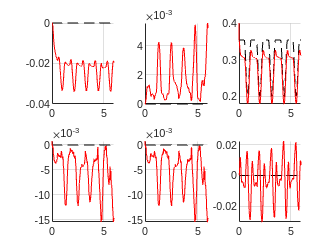

clc; close all;
lw = 1.2;
lw_gain = 2;
fs = 12;

% simStartime = 8.5;
% simEndtime = 9.5;

% Trunk Position
% fig1 = tiledlayout(3, 2, "TileSpacing", 'compact', 'Padding', 'compact');
% nexttile;
figure()
subplot(2,3,1)
hold on
plot(t, pos_trunk_des_x, 'k--');
plot(t, pos_trunk_act_x ,'r');
grid

subplot(2,3,2)
hold on
plot(t, pos_trunk_des_y, 'k--');
plot(t, pos_trunk_act_y, 'r');
grid

subplot(2,3,3)
hold on
plot(t, pos_trunk_des_z, 'k--');
plot(t, pos_trunk_act_z, 'r');
grid

subplot(2,3,4)
hold on
plot(t, rot_trunk_des_x, 'k--');
plot(t, rot_trunk_act_x ,'r');
grid

subplot(2,3,5)
hold on
plot(t, rot_trunk_des_y, 'k--');
plot(t, rot_trunk_act_y, 'r');
grid

subplot(2,3,6)
hold on
plot(t, rot_trunk_des_z, 'k--');
plot(t, rot_trunk_act_z, 'r');
grid

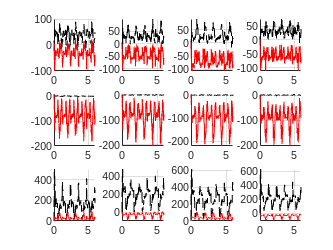


figure()
subplot(3,4,1)
hold on
plot(t, GRF_VMC_FL_x, 'k--');
plot(t, GRF_act_FL_x, 'r');
grid

subplot(3,4,2)
hold on
plot(t, GRF_VMC_FR_x, 'k--');
plot(t, GRF_act_FR_x, 'r');
grid

subplot(3,4,3)
hold on
plot(t, GRF_VMC_RL_x, 'k--');
plot(t, GRF_act_RL_x, 'r');
grid

subplot(3,4,4)
hold on
plot(t, GRF_VMC_RR_x, 'k--');
plot(t, GRF_act_RR_x, 'r');
grid


subplot(3,4,5)
hold on
plot(t, GRF_VMC_FL_y, 'k--');
plot(t, GRF_act_FL_y, 'r');
grid

subplot(3,4,6)
hold on
plot(t, GRF_VMC_FR_y, 'k--');
plot(t, GRF_act_FR_y, 'r');
grid

subplot(3,4,7)
hold on
plot(t, GRF_VMC_RL_y, 'k--');
plot(t, GRF_act_RL_y, 'r');
grid

subplot(3,4,8)
hold on
plot(t, GRF_VMC_RR_y, 'k--');
plot(t, GRF_act_RR_y, 'r');
grid

subplot(3,4,9)
hold on
plot(t, GRF_VMC_FL_z, 'k--');
plot(t, GRF_act_FL_z, 'r');
grid

subplot(3,4,10)
hold on
plot(t, GRF_VMC_FR_z, 'k--');
plot(t, GRF_act_FR_z, 'r');
grid

subplot(3,4,11)
hold on
plot(t, GRF_VMC_RL_z, 'k--');
plot(t, GRF_act_RL_z, 'r');
grid

subplot(3,4,12)
hold on
plot(t, GRF_VMC_RR_z, 'k--');
plot(t, GRF_act_RR_z, 'r');
grid


%%

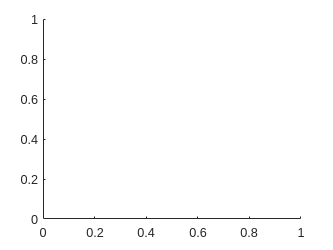

nexttile;
hold on

plot(t, imu_gyro_x, 'LineWidth', lw_gain * lw);

Unrecognized function or variable 'imu_gyro_x'.

title('Roll rate (rad/s)')
xlim([simStartime simEndtime])
grid

nexttile;
hold on
plot(t, -imu_gyro_z, 'LineWidth', lw_gain * lw);
title('Pitch rate (rad/s)')
xlim([simStartime simEndtime])
grid

% nexttile;
% hold on
% plot(t, -imu_gyro_y,   'LineWidth', lw_gain*lw);
% title('Yaw rate (rad/s)')
% grid

nexttile;
hold on
% plot(t, r_ref_FL, 'k--',   'LineWidth', lw_gain*lw);
plot(t, r_act_FL - r_act_FR, 'r-.', 'LineWidth', lw);
plot(t, r_act_RL - r_act_RR, 'b-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
title('r-position (Left - Right)')
ylabel('$r$ (m)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
grid

nexttile;
hold on
% plot(t, r_ref_FL, 'k--',   'LineWidth', lw_gain*lw);
plot(t, r_act_FL - r_act_RL, 'r-.', 'LineWidth', lw);
plot(t, r_act_FR - r_act_RR, 'b-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
title('r-position (Front - Rear)')
% ylabel('$r$ (m)','FontName','Times New Roman','interpreter','latex','FontSize',fs);
grid

nexttile;
hold on
plot(t, xdR_ref_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, xdR_act_FL - xdR_act_FR, 'r-.', 'LineWidth', lw);
plot(t, xdR_act_RL - xdR_act_RR, 'b-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
title('r-velocity (Left - Right)')
% ylabel('$r$ (m)','FontName','Times New Roman','interpreter','latex','FontSize',fs);
grid

nexttile;
hold on
plot(t, xdR_ref_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, xdR_act_FL - xdR_act_RL, 'r-.', 'LineWidth', lw);
plot(t, xdR_act_FR - xdR_act_RR, 'b-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
title('r-velocity (Front - Rear)')
% ylabel('$r$ (m)','FontName','Times New Roman','interpreter','latex','FontSize',fs);
grid

% RW tracking
figure()
fig2 = tiledlayout(2, 2, "TileSpacing", 'compact', 'Padding', 'compact');
nexttile;
hold on
plot(t, r_ref_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, r_act_FL, 'r-.', 'LineWidth', lw);
plot(t, r_act_FR, 'g-.', 'LineWidth', lw);
plot(t, r_act_RL, 'b-.', 'LineWidth', lw);
plot(t, r_act_RR, 'm-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
ylabel('$r$ (m)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
grid

nexttile;
hold on
plot(t, qr_ref_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, qr_act_FL, 'r-.', 'LineWidth', lw);
plot(t, qr_act_FR, 'g-.', 'LineWidth', lw);
plot(t, qr_act_RL, 'b-.', 'LineWidth', lw);
plot(t, qr_act_RR, 'm-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
ylabel('$\theta_r$ (rad)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
legend('Reference', 'FL', 'FR', 'RL', 'RR', 'FontName', 'Times New Roman', 'location', 'northeast')
grid

nexttile;
hold on
plot(t, xdR_ref_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, xdR_act_FL, 'r-.', 'LineWidth', lw);
plot(t, xdR_act_FR, 'g-.', 'LineWidth', lw);
plot(t, xdR_act_RL, 'b-.', 'LineWidth', lw);
plot(t, xdR_act_RR, 'm-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
ylabel('$\dot{x}^R$ (m/s)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
grid

nexttile;
hold on
plot(t, ydR_ref_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, ydR_act_FL, 'r-.', 'LineWidth', lw);
plot(t, ydR_act_FR, 'g-.', 'LineWidth', lw);
plot(t, ydR_act_RL, 'b-.', 'LineWidth', lw);
plot(t, ydR_act_RR, 'm-.', 'LineWidth', lw);
xlim([simStartime simEndtime])
xlabel(fig2, 'Time (sec)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
ylabel('$\dot{y}^R$ (m/s)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
grid

GRF Estimation

figure()
fig3 = tiledlayout(2, 2, "TileSpacing", 'compact', 'Padding', 'compact');
nexttile;
hold on
plot(t, -grf_x_FL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, -fxR_hat_FL, 'r', 'LineWidth', lw);
xlim([simStartime simEndtime])
% ylim([-200 600])
grid
ylabel('$\hat{f}^R_x$ (N)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
legend('Force Sensor', 'RWFOB', 'FontName', 'Times New Roman', 'location', 'northeast')

nexttile;
hold on
plot(t, -grf_x_FR, 'k--', 'LineWidth', lw_gain * lw);
plot(t, -fxR_hat_FR, 'r', 'LineWidth', lw);
xlim([simStartime simEndtime])
% ylim([-200 600])
grid
ylabel('$\hat{f}^R_x$ (N)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
legend('Force Sensor', 'RWFOB', 'FontName', 'Times New Roman', 'location', 'northeast')

nexttile;
hold on
plot(t, -grf_x_RL, 'k--', 'LineWidth', lw_gain * lw);
plot(t, -fxR_hat_RL, 'r', 'LineWidth', lw);
xlim([simStartime simEndtime])
% ylim([-200 600])
grid
ylabel('$\hat{f}^R_x$ (N)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
legend('Force Sensor', 'RWFOB', 'FontName', 'Times New Roman', 'location', 'northeast')

nexttile;
hold on
plot(t, -grf_x_RR, 'k--', 'LineWidth', lw_gain * lw);
plot(t, -fxR_hat_RR, 'r', 'LineWidth', lw);
xlim([simStartime simEndtime])
% ylim([-200 600])
grid
ylabel('$\hat{f}^R_x$ (N)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);
legend('Force Sensor', 'RWFOB', 'FontName', 'Times New Roman', 'location', 'northeast')

% nexttile;
% hold on
% plot(t, touch_PD,  'LineWidth', lw);
% xlim([simStartime simEndtime])
% grid
% ylabel('$\sigma_x$','FontName','Times New Roman','interpreter','latex','FontSize',fs);
% legend('Touch', 'FontName','Times New Roman','location','northeast')

xlabel(fig3, 'Time (sec)', 'FontName', 'Times New Roman', 'interpreter', 'latex', 'FontSize', fs);